clear; clc;

## get datacube

root_path = 'E:\correctedNIR\';  %D:\files\spectral_analysis\mat_demo\data
seed_variety = 'zd';
file_name0 = 25;
file_name = num2str(file_name0);

% file path
hdr_path_name = strcat(root_path, seed_variety, file_name, '_RT.hdr');
raw_path_name = strcat(root_path, seed_variety, file_name, '_RT.raw');

% get dimensions and waves
info = get_info(hdr_path_name);
[samples, lines, bands, wavelengths] = get_dimensions(info)

samples =         1004


lines =         1161


bands =         1000


wavelengths =        326.74       327.46       328.17       328.88        329.6       330.31       331.03       331.75       332.46       333.18       333.89       334.61       335.32       336.04       336.76       337.48       338.19       338.91       339.63       340.34       341.06       341.78        342.5       343.22       343.94       344.66       345.37       346.09       346.81       347.53       348.25       348.97       349.69       350.41       351.13       351.86       352.58        353.3       354.02       354.74       355.46       356.18       356.91       357.63       358.35       359.07        359.8       360.52       361.24       361.97


% get datacube

tic

rawdata = get_rawdata(raw_path_name);
rawcube0 = reshape(rawdata, [samples, bands, lines]); % contrast order to python
rawcube = permute(rawcube0, [3, 1, 2]);

toc

历时 2.425361 秒。


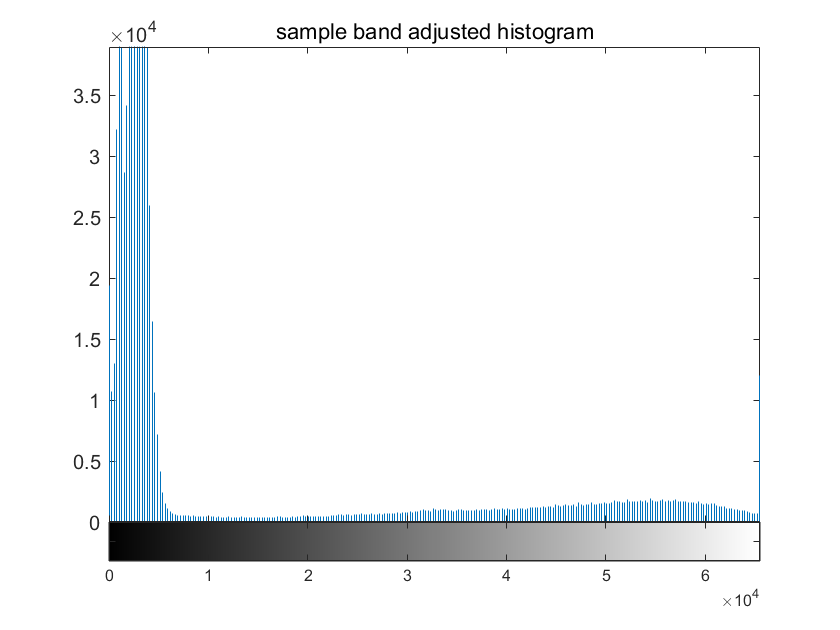

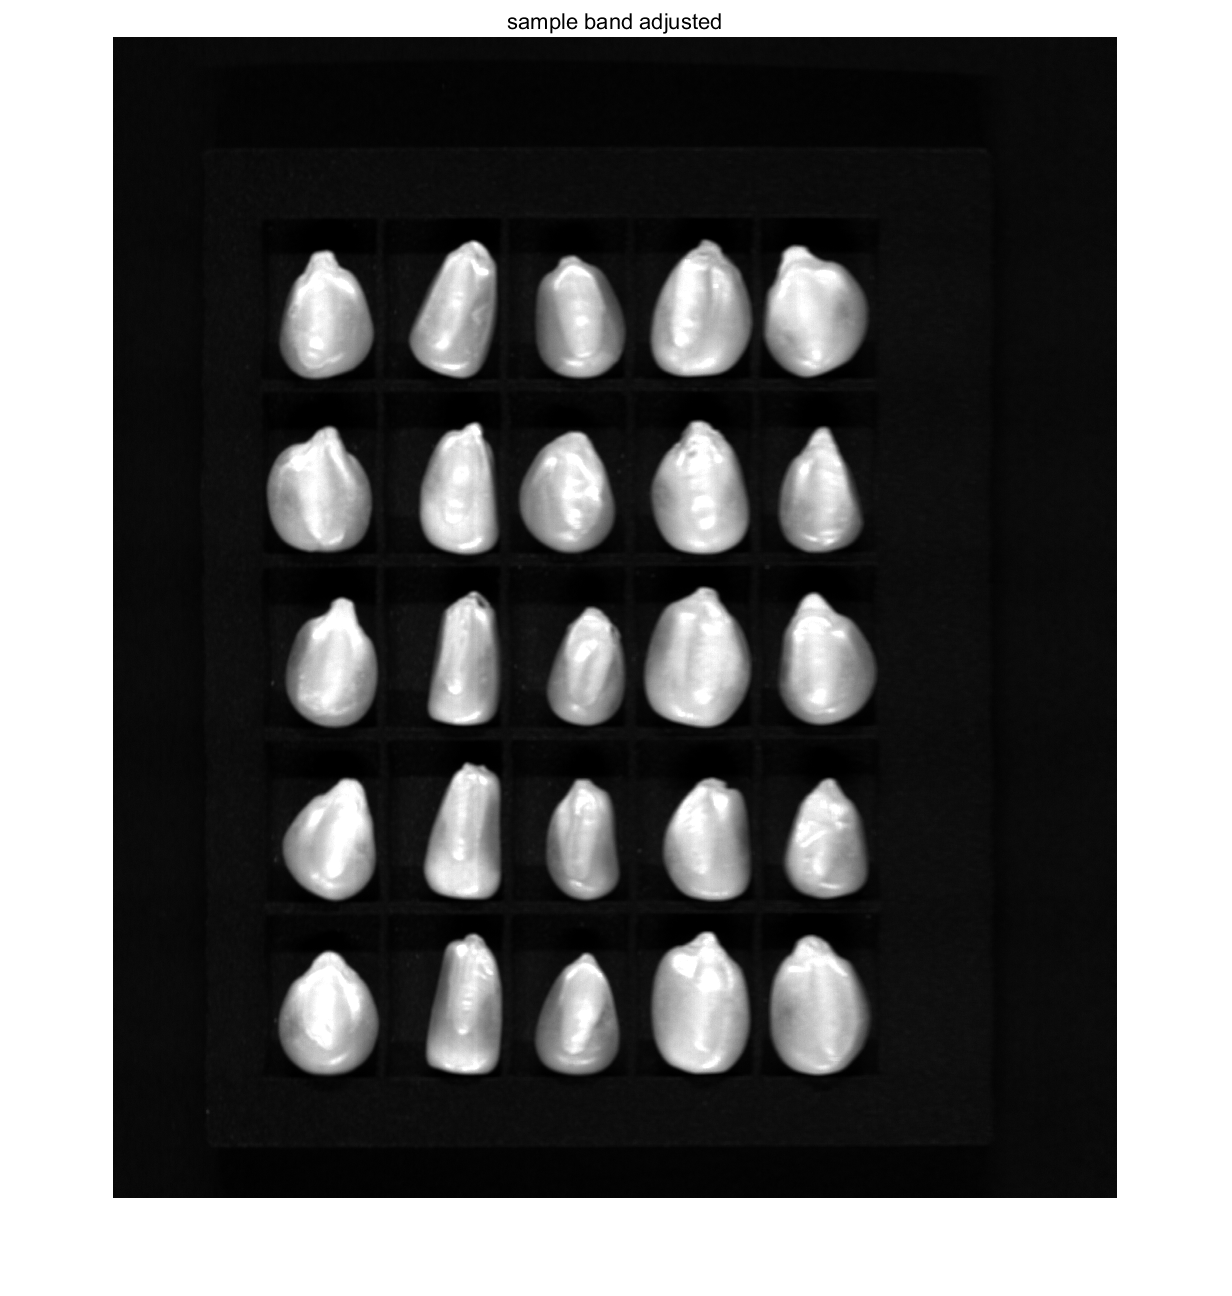

% band display  %% handi
display_band(rawcube, 500);

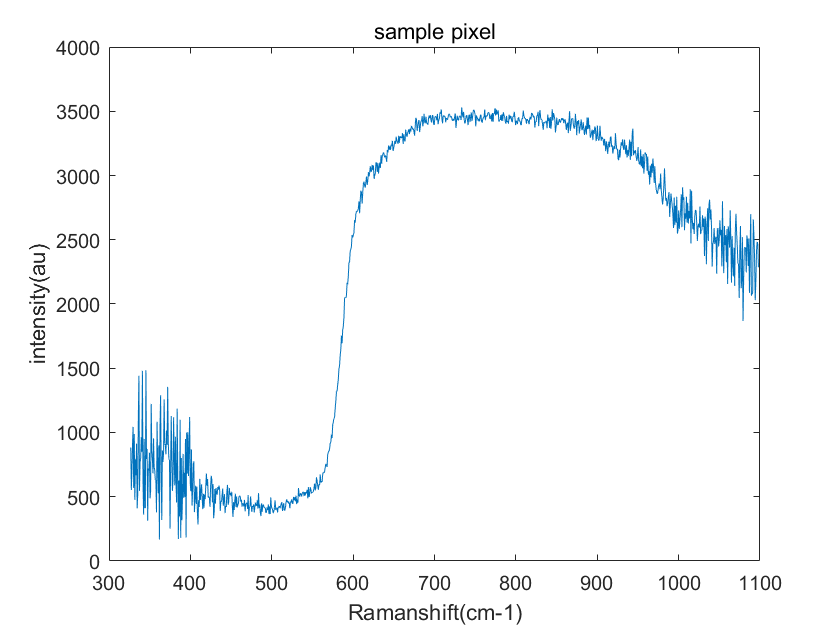

% pixel display %% handi
display_pixel(rawcube, wavelengths, 332, 216);

% effective raman shift 
[~, p1] = min(abs(wavelengths - 400));
[~, p2] = min(abs(wavelengths - 1000));
effwavelengths = wavelengths(p1:p2);

% define effcube
effcube = rawcube(:,:,p1:p2);
efflines = size(effcube, 1);
effsamples = size(effcube, 2);
effbands = size(effcube, 3);

## mask and roi

% effective band for mask
[~, b] = min(abs(effwavelengths - 880.3))

b = 624

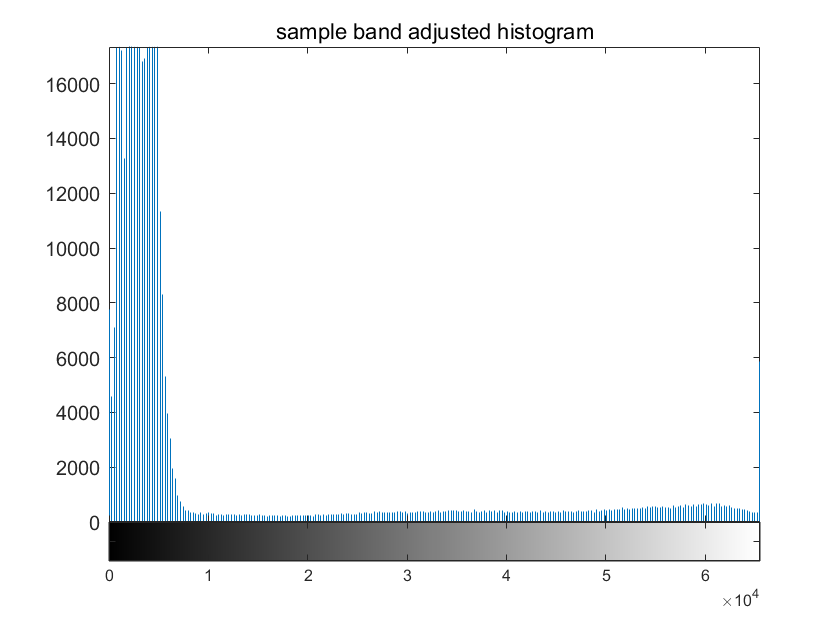

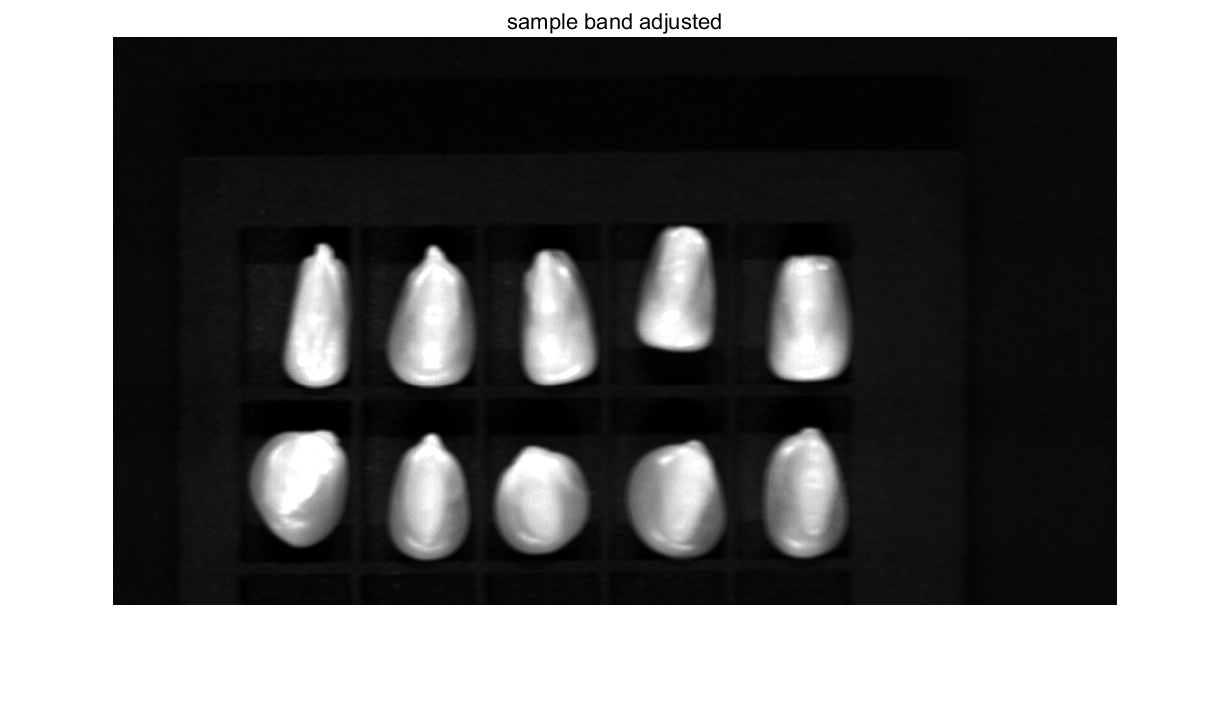

display_band(effcube, b);

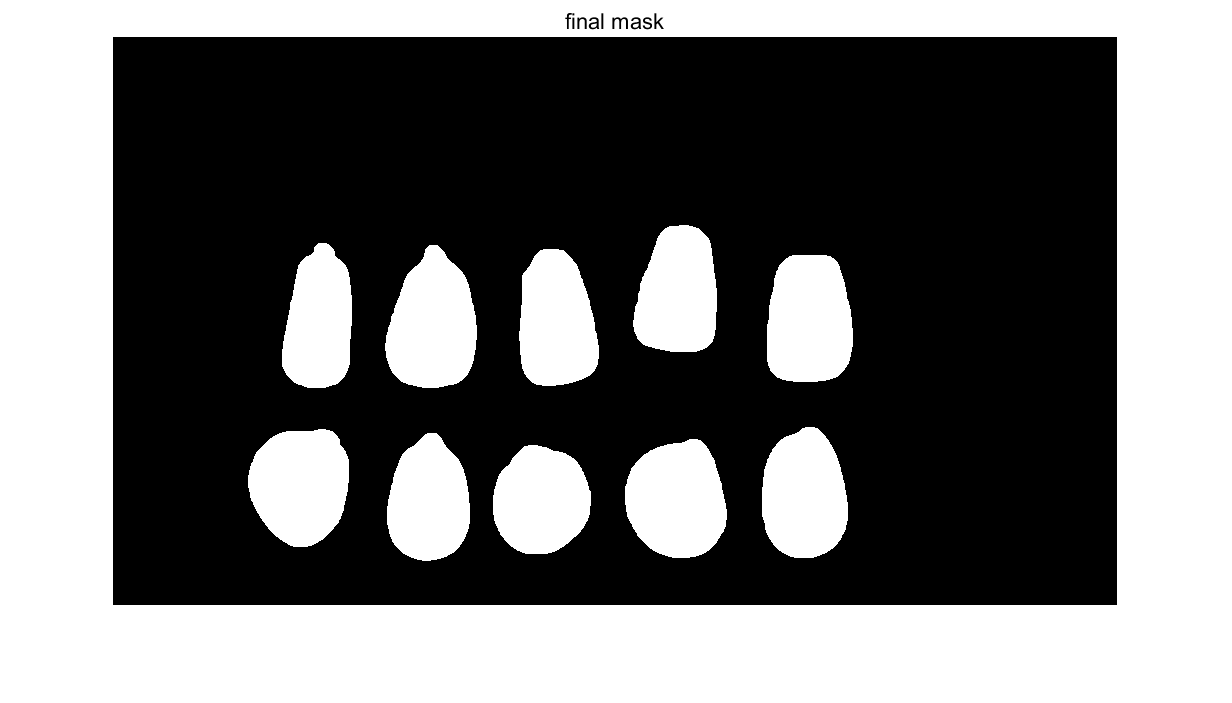

% mask  %% handi
bw = get_mask(effcube, b);

% morphology
se1 = strel('disk', 8);
se2 = strel('disk', 4);
bw_final = imopen(imclose(bw, se2), se1);
bw_final = bwareaopen(bw_final, 1000, 8);     
figure; imshow(bw_final); title('final mask')

% roi average data 
tic
[avedata, datalabel] = get_ave_spec(effcube, bw_final);
toc

历时 39.191284 秒。


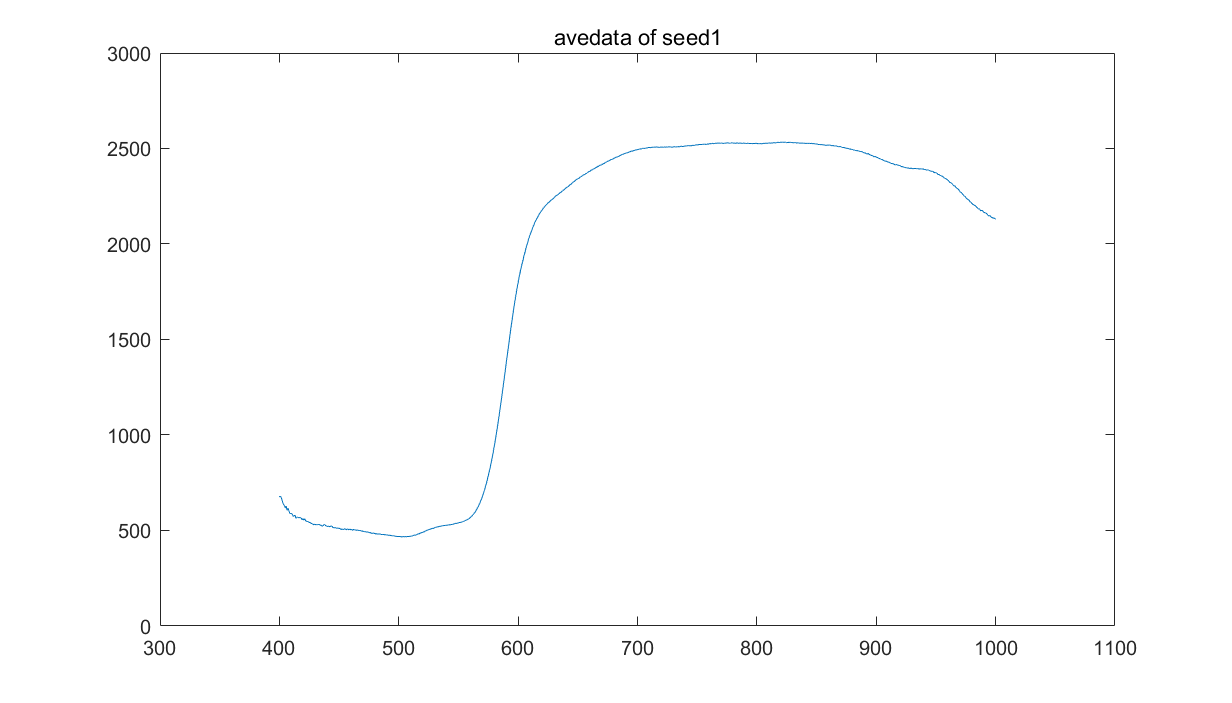

data_Pre = avedata;

plot(effwavelengths, avedata(1, :))
title('avedata of seed1')